clear all
% Load point clouds
points = [rand(1,50)'*10,rand(1,50)'*10,rand(1,50)'*10];
ptCloud1 = pointCloud(points);
ptCloud1.Color = "red"

ptCloud1 =   pointCloud with properties:

     Location: [50×3 double]
        Count: 50
      XLimits: [0.2318 9.9739]
      YLimits: [0.1286 9.9016]
      ZLimits: [0.0896 9.9142]
        Color: [50×3 uint8]
       Normal: []
    Intensity: []


ptCloud2 = pointCloud(points*-eye(3,3) + [1,.76,.28]);
ptCloud2.Color = "blue"

ptCloud2 =   pointCloud with properties:

     Location: [50×3 double]
        Count: 50
      XLimits: [-8.9739 0.7682]
      YLimits: [-9.1416 0.6314]
      ZLimits: [-9.6342 0.1904]
        Color: [50×3 uint8]
       Normal: []
    Intensity: []


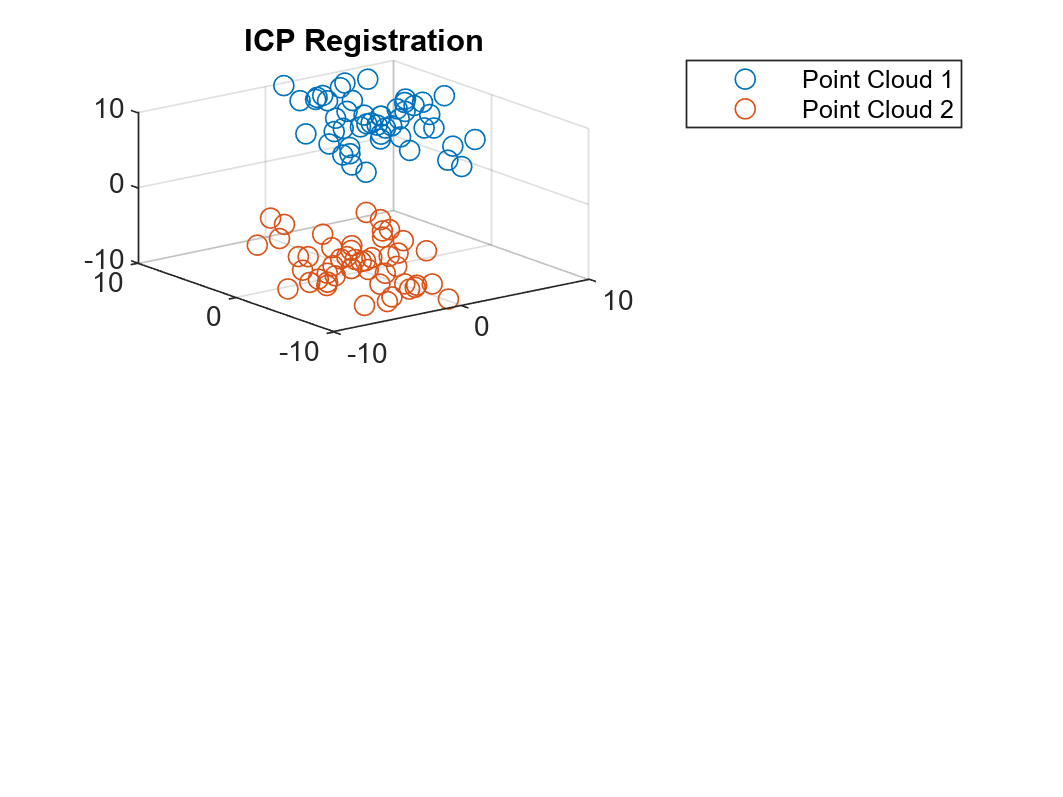


% Initialize plot
figure;
subplot(2,1,1)
% h1 = pcshow(ptCloud1, 'MarkerSize', 25, "AxesVisibility","on");
h1 = scatter3(ptCloud1.Location(:,1), ptCloud1.Location(:,2), ptCloud1.Location(:,3));

hold on;
% h2 = pcshow(ptCloud2, 'MarkerSize', 25, "AxesVisibility","on");
h2 = scatter3(ptCloud2.Location(:,1), ptCloud2.Location(:,2), ptCloud2.Location(:,3));

title('ICP Registration');
legend('Point Cloud 1', 'Point Cloud 2');


maxIterations = 100;
tolerance = 1e-6

tolerance = 1.0000e-06

for i = 1:maxIterations
    % Find nearest neighbors
    idx = findNearestNeighbors(ptCloud1.Location, ptCloud2.Location);
    
    % Estimate transformation
    [R, t] = estimateTransform(ptCloud1.Location, ptCloud2.Location(idx,:));
    Tnew = eye(4);
    Tnew(1:3,1:3) = R;
    Tnew(1:3,4) = t;
    
    % Update transformation
%     T = Tnew * T
    ptCloud1 = pctransform(ptCloud1, rigidtform3d(R,t));
    
    % Compute error
    error = computeError(ptCloud1.Location, ptCloud2.Location, Tnew);

    
    % Plot intermediate results
    set(h1, 'XData', ptCloud1.Location(:,1), 'YData', ptCloud1.Location(:,2), 'ZData', ptCloud1.Location(:,3));
    title(sprintf('ICP Registration (Iteration %d)\nError: %f', i, error));
    drawnow;
    
    % Check convergence
    if error < tolerance
        break;
    end
end

% Plot final result
set(h1, 'XData', ptCloud1.Location(:,1), 'YData', ptCloud1.Location(:,2), 'ZData', ptCloud1.Location(:,3));
title(sprintf('ICP Registration (Iteration %d)\nError: %f', i, error));


function [dist_index, dist_list] = findNearestNeighbors(points_a, points_b)
%     % Find nearest neighbors between two point clouds using KD-tree
%     tree = KDTreeSearcher(ptCloud2);
%     [idx, dist] = knnsearch(tree, ptCloud1);

dist_index = zeros(length(points_a), 1);
dist_list = zeros(length(points_a), 1);
for i = 1:length(points_a)
    shortest_distance = 100;
    a_i = points_a(i);
    for j = 1:length(points_b) %for each sample point
          b_i = points_b(j);
             dist = (norm(a_i - b_i));
        if dist < shortest_distance
            shortest_distance = dist;
            short_dist_index = j;
            dist_index(i) = short_dist_index';
              dist_list(i) = shortest_distance';
        end
    end
    
end
end


function [R, t] = estimateTransform(ptCloud1, ptCloud2)
    % Estimate rigid transform using SVD
    X = ptCloud1;
    Y = ptCloud2;
    X_bar = mean(X);
    Y_bar = mean(Y);
    X_tilde = X - X_bar;
    Y_tilde = Y - Y_bar;

    H = 0;
    for i = 1:length(X)
        X_tilde_i = X_tilde(i, :);
        Y_tilde_i = Y_tilde(i, :);
        H_i = X_tilde_i' * Y_tilde_i;
        H = H + H_i;
    end
%     H = X_tilde * Y_tilde';
    [U, ~, V] = svd(H);
    R = V * U';
    if det(R) ~= 0
        disp('algorithm may fail')
        return
%         V(:, end) = -V(:, end);
%         R = V * U';
    end
    t = Y_bar' - R * X_bar';
end

function [rmse, indices] = computeError(ptCloud1, ptCloud2, T)
    % Transform ptCloud1 using T and compute RMSE
    ptCloud1Transformed = (T * [ptCloud1'; ones(1, size(ptCloud1, 1))])';
    ptCloud1Transformed = ptCloud1Transformed(:, 1:3);   
    idx = findNearestNeighbors(ptCloud1Transformed, ptCloud2);
    rmse = sqrt(mean(sum((ptCloud1Transformed - ptCloud2(idx, :)).^2, 2)));
    indices = idx;
end




